# ENGR105    ---    Problem Set 5    ---   Decisions, functions, and more

## Due: Friday, 10/2/2020

## Name:

#### The University of Pennsylvania code of academic integrity can be found here:

[https://catalog.upenn.edu/pennbook/code-of-academic-integrity/](https://catalog.upenn.edu/pennbook/code-of-academic-integrity/)

By submitting this assignment, you certify that you completed this assignment in compliance with the code of academic integrity, as defined above, and that the work here is your own. Collaboration is allowed and encouraged but  it is in your own best interest to be able to complete all the problems on your own. Collaboration is allowed, COPYING is NOT. Be sure you are able to reason through each step. 

#### Notes on HW submission:

- Please save the final document In the following format: "<your last name>_<your first name>_HW5.mlx

- Run the entire document (`f5`) prior to submitting. Following this, please **export to .pdf** and **submit both** the .mlx file and the .pdf file to Canvas.

- The LiveScript file may be exported to PDF using the **Save** dropdown menu. **Please also see my recent email regarding alternative methods for exporting to PDF.**

- If it is not selected by default, select "Output Inline" at the top right of the LiveScript document to display the output below your code (rather than to the right).

#### Purpose of this problem set:

- Practice applying conditional statements, loops, and functions, to solve problems.

#### Notes about MATLAB LiveScripts:

- The gray regions are "code" regions. Entering and running your code here is the same as running it in a `.m` script file or on the command line.

- "Running a piece of code" means you are executing the code in that section only. **Press **`Cntl`** + **`Enter`** to run a given section.**

- Press `f5` to run all sections of the document.

- To remove inline figures, right click and select "Clear All Output."

- When you run a section (each section refers to a different problem or part of a problem), all variables and vectors are stored in MATLAB and may be called from the command line.

**Reminder: Prior to submitting, be sure to run ****all**** sections of the document to ensure that it works properly. After running all sections, export the document to pdf.**

## PROBLEM 1 (20 pts): Conditionals and decisions

Having realized you don't need dollar bills to have fun tonight (because you love cheap thrills), you attend a 2010s themed party. Your hat is matte black, got the boots that's black to match; needless to say, you have high, high hopes. 

At the party, *you want to determine if*:

- It's too hot (hot damn), make a dragon wanna retire, man [*the temperature is too hot and you should leave*]

- You should come on and come on and raise your glass [*you should get a drink*]

- You'll be dancing on your own (dancing on your own), making the moves up as you go [*you should dance*]

However, as an engineer, you want to make an objective decision based on measured data. For this reason, you decide to measure three variables at two points (**t1 **first, and then **t2**, some time later):

- Your temperature (in degrees Fahrenheit)

- Your sleepiness (on a scale in which higher numbers indicate increased sleepiness)

- Your thirst (on a scale in which higher numbers indicate increased thirst)

You organize this information mentally in the form of a `3x2` matrix, where the position in the matrix where a number is stored indicates which variable it corresponds to.

                
$$\textrm{party}\_\textrm{state}=\left\lbrack \begin{array}{cc}
\textrm{Temperature}\;\textrm{t1} & \textrm{Temperature}\;\textrm{t2}\\
\textrm{Sleepiness}\;\textrm{t1} & \textrm{Sleepiness}\;\textrm{t2}\\
\textrm{Thirst}\;\textrm{t1} & \textrm{Thirst}\;\textrm{t2}
\end{array}\right\rbrack$$


Furthermore, you decide what to do based on the following decision tree. 

        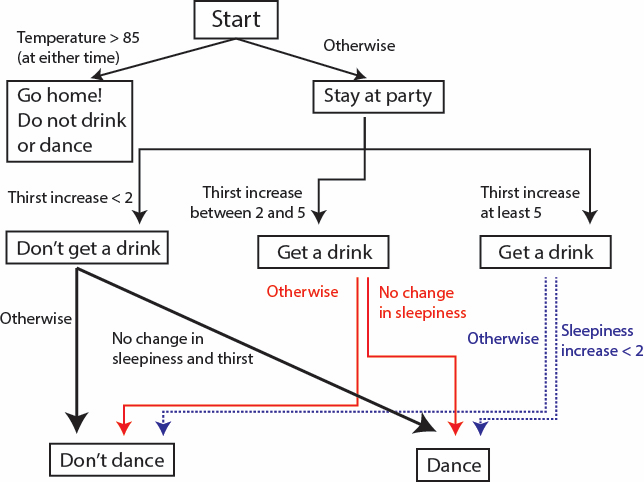

**Produce a script based on the above decision tree that produces **$\textrm{party}\_\textrm{decision}$, **a 3x1 vector (of the following form), indicating the choices made at the party**.

            
$$\textrm{party}\_\textrm{decision}=\left\lbrack \begin{array}{c}
\textrm{Stay}?\\
\textrm{Drink}?\\
\textrm{Dance}?
\end{array}\right\rbrack$$


The values of the entries in each position of* party_decision* should be either `1` (`true`) or `0` (`false`) indicating if you decide to stay, get a drink (of water), or dance, respectively. 

For example, if you decide to stay, dance and not drink, the output should be:

            
$$\textrm{party}\_\textrm{decision}=\left\lbrack \begin{array}{c}
1\\
0\\
1
\end{array}\right\rbrack$$


However, if you decide to leave without dancing or drinking, your answer should be:

            
$$\textrm{party}\_\textrm{decision}=\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$$


**Test your script by running the following **`party_state`** matrix.**

% Matrix containing your measured data points
party_state = [77,80;23,21;17,35];
party_decision = ones(3,1);
temp1 = party_state(1,1);
temp2 = party_state(1,2);
sleepiness = party_state(2,:);
thirst = party_state(3,:);
thirst_change = abs(party_state(3,1) - party_state(3,2));
sleepiness_change = abs(party_state(2,1) - party_state(2,2));
%three options, leaving, drinking, dancing 
 
%if thirst increases from the frist trip to sometime later, you should get
%a drink

% temp >85 person should just go home 

%should get staying, dont drink, dont dance 
% [ 1,0,0]
if temp1 > 85 && temp2 > 85
    party_decision(1) = false;
else
    party_decision(1) = true;
    if thirst_change >=2 && thirst_change > 5
        party_decision(2) = true;
    else 
        party_decision(2) = false; 
    end
end 
if party_decision(2) == true && sleepiness_change == 0 
    party_decision(3) = true; 
elseif party_decision(2) == true && sleepiness_change > 2
    party_decision(3) = true; 
elseif party_decision(2) == false && sleepiness_change == 0 && thirst_change == 0
    party_decision(3) = true;
else
    party_decision(3) = false; 
    
end

disp(party_decision)

     1
     1
     0



In your final script, all outputs should be suppressed **except** for the vector `party_decision `so that the results from your code are clearly visible.

## PROBLEM 2 (25 pts): Calculating the n-th root

Mathematical procedures for finding the roots (especially square roots) of numbers date back millenia, with some known since at least the period of ancient Babylon in the 17th century BC! Many of these procedures are iterative, just like the **numerical method** we used in class (**the Newton-Raphson method**) to determine the** roots of a function** to some pre-specified tolerance. In this problem, you will add to the millenia of human effort in this topic by creating a function (that uses the Newton-Raphson method) to numerically calculate the n-th root of *any* positive integer.

**a)** Create a function, using the Newton-Raphson method, that is capable of determining the n-th root of any arbitrary, positive number. You should not use any built-in functions in MATLAB to evaluate the power of a number, nor should you use any other algorithm. Your function should have the following characteristics:

- It should have the name `calculateNthRoot()` and be contained in the space provided in this LiveScript document.

- It should take **three scalar inputs.** The first input should be a scalar (integer) specifying n, the root that is to be solved for. The second should be a scalar specifying the number to take the n-th root of. 

- The third input should be the *tolerance*. Your iterative method should terminate (and the numerical approximation returned) when the absolute value of the difference between $x_n$ and $x_{n+1}$ is less than the input tolerance.

- For example, `calculateNthRoot(b,a,10^-5)` should numerically calculate $a^{\left(\frac{1}{b}\right)}$ by applying the Newton-Raphson method, with the iterations ending once $\left|x_n -x_{n+1} \right|<{10}^{-5}$.

- Your function should produce **one output**: the n-th root of the specied number.

- As always, your code should be clear and well-commented.

**Hint**: each of the following mathematical expressions are equivalent.

                
$$\begin{array}{l}
x=\sqrt{a}\\
x^2 =a\\
x^2 -a=0
\end{array}$$


**b) **Using your function, numerically calculate $\sqrt{2}$. Specify a tolerance of ${10}^{-6}$`.` Assign the output from your function to the variable `p2_b` and display the value of this variable after running your code.

calculateNthRoot((2),2,10^(-6))

nth_root = 1.4142

ans = 1.4142

**c)** Using your function, numerically calculate $\sqrt[3]{10}$. Specify a tolerance of ${10}^{-6}$`. `Assign the output from your function to the variable `p2_c` and display the value of this variable after running your code.

calculateNthRoot((3), 10, 10^(-6))

nth_root = 2.1544

ans = 2.1544

## PROBLEM 3 (55 pts): Sorting algorithms

Have you ever received a call from a telemarketing company, obtained directions using google maps, or played an online card game? These are just some of many situations in which sorting is productively (or in the case of telemarketing, unproductively) used in the real world. There are many sorting algorithms, each with varying speed, memory requirements, and ease of implementation. If you are interested, this website describes many of the most popular sorting methods:

[https://www.toptal.com/developers/sorting-algorithms](https://www.toptal.com/developers/sorting-algorithms)

In this problem, you will implement bubble sort and insertion sort algorithms and compare the speed of each of your implementations to the built-in sorting method in MATLAB. All of your sorting methods should sort in descending order. Consider the following vector `v`, which we will use to test two different sorting algorithms.

v = [7.3,5.4,2.4,8.7,3.6]

v =     7.3000    5.4000    2.4000    8.7000    3.6000


#### **a) Bubble Sort (20 pts)**

The bubble sort algorithm consists of **stepping through each index** of an incoming list (*e.g.* a vector) of numbers, comparing adjacent terms, and **swapping the terms if they are in the "wrong" order**. This process is repeated until the list of numbers is fully sorted.

**Demonstration**. A bubble sort algorithm used to sort the vector from** largest to smallest** values would take the following steps. The bold/underlined indices are "under consideration" in each step.

**step 1**: `[``7.3, 5.4``, 2.4, 8.7, 3.6]` → 7.3 > 5.4, the elements are not swapped

**step 2**: `[7.3, ``5.4, 2.4``, 8.7, 3.6]` → 5.4 > 2.4, the elements are not swapped

**step 3**: `[7.3, 5.4, ``2.4, 8.7``, 3.6]` → 2.4 < 8.7, the elements are swapped

**step 4**: `[7.3, 5.4, 8.7, ``2.4, 3.6``]` → 2.4 < 3.6, the elements are swapped

**step 5**: `[``7.3, 5.4``, 8.7, 3.6, 2.4]` → 7.3 > 5.4, the elements are not swapped

**step 6**: `[7.3, ``5.4, 8.7``, 3.6, 2.4]` → 5.4 < 9.7, the elements are swapped

**step 7**: `[7.3, 8.7, ``5.4, 3.6``, 2.4]` → 5.4 > 3.6, the elements are not swapped

**step 8**: etc.

This algorithm *continues until a full sweep of the vector does not yield any swaps *(i.e. the list is fully sorted).

***i)***** Create a function **(in the space provided at the end of this LiveScript document) that sorts an input vector using the **bubble sort algorithm**. Your function should have the following characteristics:

- It should have the name `bubble_sort()` and be contained in the space provided in this LiveScript document.

- It should take **one input: **a `1xn` row vector containing the list of numbers to be sorted.

- It should produce **two outputs**: the first output should be the **computational time** required to sort the input vector `v`, and the second output should be the **sorted** vector.

- The alrogithm contained within the function should use the **bubble sort algorithm** and sort in descending order. That is, the first element of the sorted vector should be the largest number that is contained within the vector.

***ii)*** Run `bubble_sort()` on vector `v`, defined above, to convince yourself that the algorithm is working properly. Display the sorted vector.

bubble_sort(v)

ans =     7.3000    8.7000    5.4000    2.4000    3.6000


#### **b) Insertion Sort (20 pts)**

The insertion sort algorithm consists of **investigating each element in a set of numbers** to be sorted (starting with the second index of the set) and determining where the element of interest should be inserted in the set of numbers that has already been sorted (*i.e.* the set of numbers preceding the number to be sorted).

**Demonstration**. An insertion sort algorithm used to sort the vector from** largest to smallest** values would take the following steps. The bold/underlined indices are under consideration in each step.

**step 1**: `[7.3, ``5.4``, 2.4, 8.7, 3.6]` → index 2 is under consideration, 5.4 is smaller than the value stored in all indices preceding it (index 1) and is not relocated.

**step 2**: `[7.3, 5.4, ``2.4``, 8.7, 3.6]` → index 3 is under consideration, 2.4 is smaller than the values stored in the indices preceding it (indices 1 and 2) and is not relocated.

**step 3**: `[7.3, 5.4, 2.4, ``8.7``, 3.6]` → index 4 is under consideration, 8.7 is larger than the values stored in the indices preceding it (indices 1, 2, and 3), so* 8.7 is placed in index 1 and all other indices are shifted to the right*

**step 4**: `[8.7, 7.3, 5.4, 2.4, ``3.6``]` → index 5 is under consideration, 3.6 is larger than *only some* of the values stored in the indices preceding it (index 4), so *3.6 is placed in index 4, 2.4 shifts to the right, and all other indices remain in place*.

The vector is now sorted: `[8.7, 7.3, 5.4, ``3.6, ``2.4].`

***i)***** Create a function **(in the space provided at the end of this LiveScript document) that sorts an input vector using the **insertion** **sort algorithm**. Your function should have the following characteristics:

- It should have the name `insertion_sort()` and be contained in the space provided in this LiveScript document.

- It should take **one input: **a `1xn` row vector containing the list of numbers to be sorted.

- It should produce **two outputs**: the first output should be the **computational time** required to sort the input vector `v`, and the second output should be the **sorted** vector.

- The alrogithm contained within the function should use the **insertion sort algorithm** and sort in descending order. That is, the first element of the sorted vector should be the largest number that is contained within the vector.

***ii)*** Run `insertion_sort()` on vector `v`, defined above, to convince yourself that the algorithm is working properly. Display the sorted vector.

insertion_sort(v)

ans = 2.3817e-04

#### **c) Comparison to the built-in **`sort()`** function (15 pts)**

MATLAB has a built-in sorting function `sort()` that may be used to sort lists in either ascending or descending order. **Create a script** that compares the computational efficiency of `bubble_sort()`, `insertion_sort()`, and the `sort()` function.

Specifically, you should test how long each function takes to sort a `1xn`** vector of random numbers** (generated using the `rand()` function). **Perform this test for 20 values of **`n`** evenly spaced from 50 to 2000 **and** plot the computation time as a function of n, **the *length* of the sorted vector. 

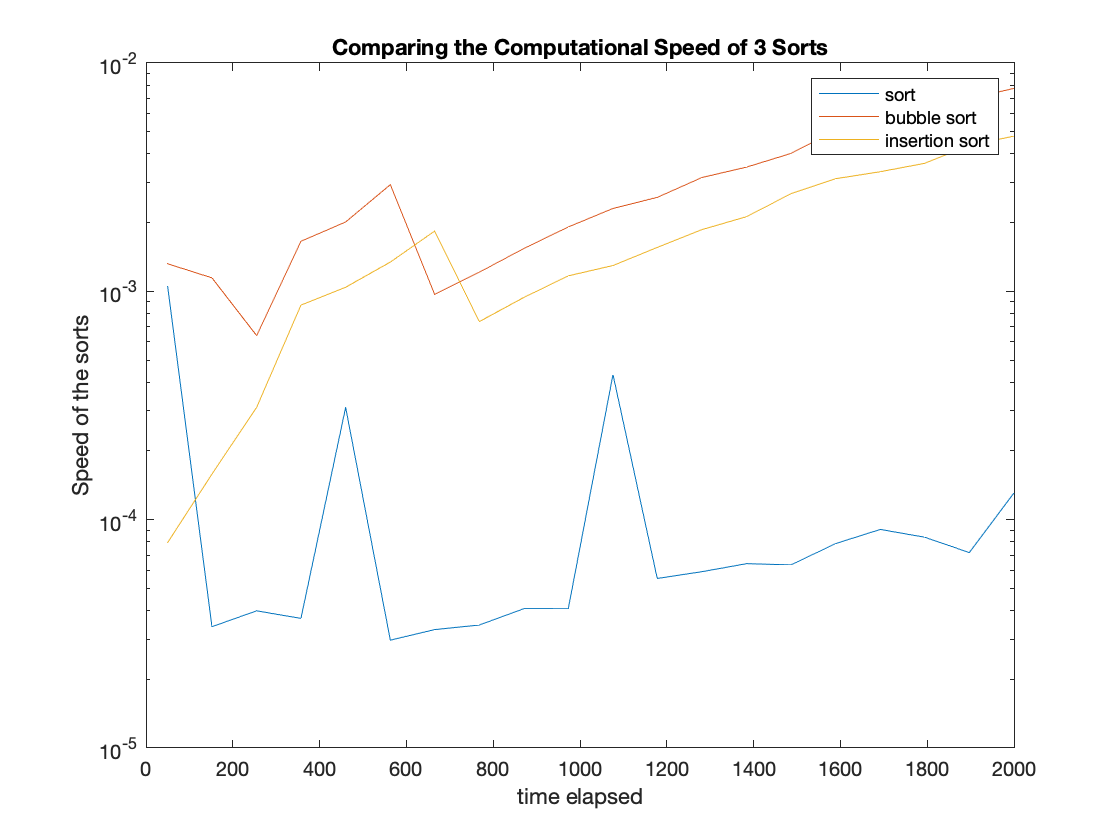

%functions to hold the values of the times 
time_sort = zeros(1,20);
time_bubble = zeros(1,20);
time_insertion = zeros(1,20);
%counter to go through all of the time vertices
i = 1;

for k = floor(linspace(50,2000,20))
    v = rand(1,k);
    %time for sort function
    tic; 
    sort(v, 'descend');
    time_sort(i) = toc;
   
    %time for bubble sort 
    tic;
    bubble_sort(v);
    time_bubble(i) = toc;
    
    %time for insertion sort
    tic;
    insertion_sort(v);
    time_insertion(i) = toc; 
    
    %increases as you go through the loop
    i = i+1;
end

n = floor(linspace(50,2000,20));
semilogy(n,time_sort, n, time_bubble, n, time_insertion)
legend('sort', 'bubble sort', 'insertion sort')
xlabel('time elapsed')
ylabel('Speed of the sorts')
title('Comparing the Computational Speed of 3 Sorts')

Your plot should include a linear x-axis, a logarithmic y-axis, axis titles, plot title, and a legend. Your plot should be clear and look professional.

**Note**: sort times will be dependent on the efficiency of your code. You may or may not find that your insertion sort algorithm is faster than your bubble sort algorithm.

## Problem Set 5: functions stored below

**Use the space below for PROBLEM 2.**

function nth_root = calculateNthRoot(n,x,tolerance)
% n is amount of terms, x is number, tolerance is the error
%finds root by finding where it is tangent to the function
%step 1: pick initial guess
%step 2: iterate from xn to xn+1
%step 3: xn+1 from xn
%step 4: compare xn and xn+1 and see if loop should continue
y = 1;
prev_y = 0;
    while abs(y-prev_y) > tolerance 
        z = y^n - x; 
        %derivative of z
        zprime = n*y^(n-1);
        %resets y to what it was before 
        prev_y = y;
        %sets the new y value to something different
        y = y-z/zprime;
    end
nth_root = y
end







**Use the space below for PROBLEM 3, a).**

%create a function that swaps numbers if one is greater than the other 
%largest to smallest

% needs to continue to iterate until the front is the largest number 
function [v,time] = bubble_sort(v)
    tic;
    filler = 0;
    i = 1;
    %loop can run through the whole vector in order to check every position 
    %attempted using a while loop, may not work 
    for k = 1:length(v)-1
        %itera
        for i = 2:length(v) - k - 1
        %stores the next vairable, and checks if the current index is less
        %than the next one 
            if v(i) < v(i+1)
                filler = v(i+1);
                v(i+1) = v(i);
                v(i) = filler;  
            end
            i = i-1;
        end
    end
    
    
    time = toc;
end









**Use the space below for PROBLEM 3, b).**

%relate the numbers to the ones before it 
%if it is greater than that number you insert it there and shift everything
%else to the right 
%goes to position of the last number it is greater than and shifts
%everything 

% new method is to expand array, rearange and then delete extra space
%compare choice index to those before it 
function [time, output] = insertion_sort(v)
    %initially makes false incase if does not work
    condition = true;
    
    while condition
        tic;
        condition = false;
        for k = 2:length(v)
            %checks every indice inside the vector
            for i = 1:k-1
                %checks if the number before is greater and if so,
                %replace
                if v(i) < v(k)
                    v = [v(1:i-1), v(k), v(i:end)];% inserts the number and increases the length 
                    v(k+1) = []; %makes last number empty
                    condition = true;
                end 
            end
        end 
    end
    output = v;
    time = toc;
end

%     %iterates through starting at the second indice 
%     for k = 2:length(v)
%         %create a new variable to run through the vector 
%         i = k-1;
%         index = i;
%         %iterates through until the vector is arranged
%         while i>=1
%             if v(index)<(i)
%                 filler = v(i);
%                 v(i) = v(index);
%                 v(index) = filler;
%                 index = i;
%             end
%             i = i-1;
%         end
%     end
%    output = v
%    time = toc;
